# PCA and Eigen Values

clear all
clc

RGB_Img = im2double(imread('chicken.jpg'));
N = size(RGB_Img, 1)*size(RGB_Img, 2);
[height,width,depth] = size(RGB_Img);


R = RGB_Img(:, :, 1);
G = RGB_Img(:, :, 2);
B = RGB_Img(:, :, 3);

R_mean = sum(sum(R))/N;
G_mean = sum(sum(R))/N;
B_mean = sum(sum(R))/N;

## Covariance


C = zeros(3, 3);

C(1, 1) = sum(sum((R - R_mean).*(R - R_mean)))/N;
C(2, 2) = sum(sum((G - G_mean).*(G - G_mean)))/N;
C(3, 3) = sum(sum((B - B_mean).*(B - B_mean)))/N;
C(1, 2) = sum(sum((R - R_mean).*(G - G_mean)))/N;
C(1, 3) = sum(sum((R - R_mean).*(B - B_mean)))/N;
C(2, 1) = sum(sum((G - G_mean).*(R - R_mean)))/N;
C(2, 3) = sum(sum((G - G_mean).*(B - B_mean)))/N;
C(3, 1) = sum(sum((B - B_mean).*(R - R_mean)))/N;
C(3, 2) = sum(sum((B - B_mean).*(G - G_mean)))/N;

disp('The Covariance Matrix is as follows: C = ')

The Covariance Matrix is as follows: C = 


disp(C)

    0.0824    0.0773    0.0665
    0.0773    0.0776    0.0682
    0.0665    0.0682    0.0640



## Eigen Values aand Eigen Vectors

[v, d] = eig(C);

d = [d(3,3) 0 0; 0 d(2, 2) 0; 0 0 d(1, 1)];
A = [v(:, 3) v(:, 2) v(:, 1)];

disp('Eigenvalues arranged in descending order are:')

Eigenvalues arranged in descending order are:


disp(d(1, 1))

    0.2168



disp(d(2, 2))

    0.0061



disp(d(3, 3))

    0.0012




disp('Corresponding eigenvector matrix is as follows:')

Corresponding eigenvector matrix is as follows:


disp(A)

    0.6047   -0.7022   -0.3759
    0.5953    0.0850    0.7990
    0.5291    0.7069   -0.4694



## Applying PCA


A = A';
transformed = A*([R(:), G(:), B(:)] - repmat([R_mean G_mean B_mean], N, 1))';
c = 0;
d = 255;

transformed_R = transformed(1, :);
max_transformed_R = max(transformed_R);
min_transformed_R = min(transformed_R);
mapped_R = ((c+d) + (d-c)*((2*transformed_R - (min_transformed_R+max_transformed_R))/(max_transformed_R-min_transformed_R)))/2;


transformed_G = transformed(2, :);
max_transformed_G = max(transformed_G);
min_transformed_G = min(transformed_G);
mapped_G = ((c+d) + (d-c)*((2*transformed_G - (min_transformed_G+max_transformed_G))/(max_transformed_G-min_transformed_G)))/2;


transformed_B = transformed(3, :);
max_transformed_B = max(transformed_B);
min_transformed_B = min(transformed_B);
mapped_B = ((c+d) + (d-c)*((2*transformed_B - (min_transformed_B+max_transformed_B))/(max_transformed_B-min_transformed_B)))/2;

Y_1 = reshape(mapped_R(1, :), height, width);
Y_2 = reshape(mapped_G(1, :), height, width);
Y_3 = reshape(mapped_B(1, :), height, width);


## Displaying Results

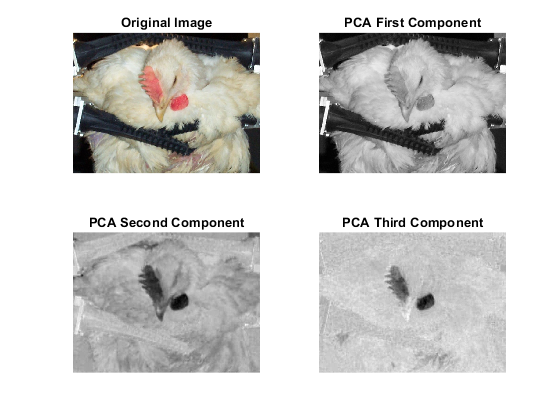

figure()
subplot(2,2,1) 
imshow(RGB_Img);
title('Original Image')
subplot(2,2,2)
imshow(Y_1,[]);
title('PCA First Component')
subplot(2,2,3)
imshow(Y_2,[]);
title('PCA Second Component')
subplot(2,2,4)
imshow(Y_3,[]);
title('PCA Third Component')